proccessed = experiment1;
fpms = 50;
totalTime = size(experiment1, 3)/fpms;
msPerFrame = 1/fpms;
micronsPerXPixel = 13.5;
micronsPerZPixel = 50;

**Smoothing**

smoothing = true;
if(smoothing)
    timeSmoothing = 1;
    threshold = 0.985;
    xSmoothing = 21;
    zSmoothing  = 21;
    proccessed = SmoothExperiment(experiment1, timeSmoothing, threshold, zSmoothing, xSmoothing);
else
    processed = experiment1;
end

**Plot Experiment**

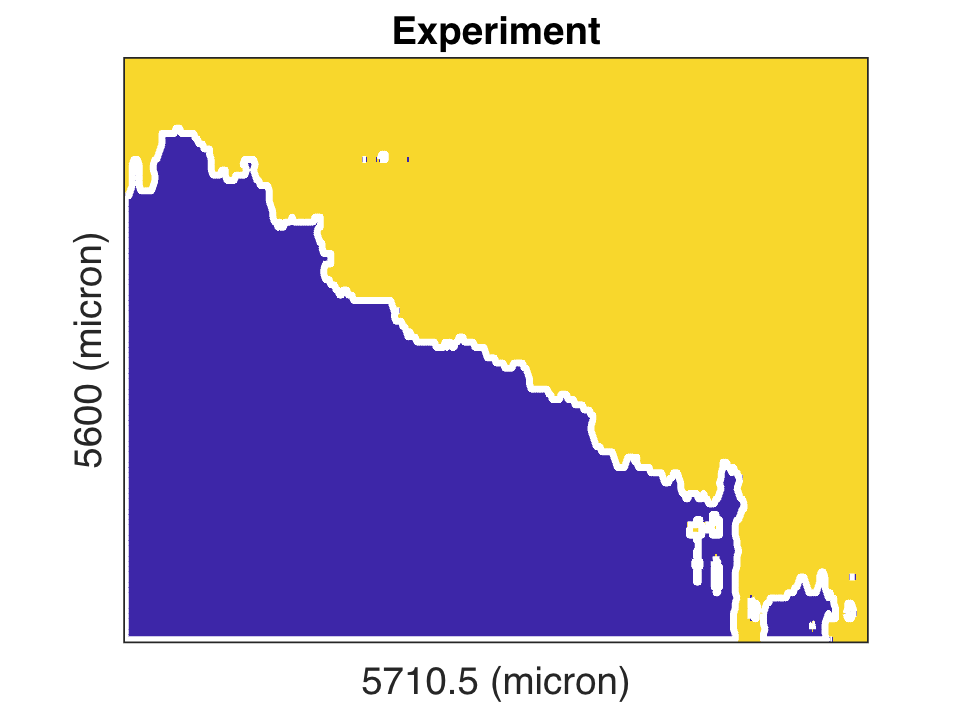

t=1.8;
current = proccessed(:,:,round(t*fpms)+1);
imagesc(current);
caxis([0.9 1.01]);
if(~smoothing)
    colorbar;
end
title("Experiment");
xticks([]);
yticks([]);
xlabel(micronsPerXPixel * size(experiment1,2) + " (micron)");
ylabel(micronsPerZPixel * size(experiment1,1) + " (micron)");

% plot front
if(smoothing)
    boundaries = bwboundaries(~current);
    hold on;
for k = 1:length(boundaries)
   boundary = boundaries{k};
   plot(boundary(:,2), boundary(:,1), 'w', 'LineWidth', 2)
end
hold off;
end